Author@ B.C Yang (2023)

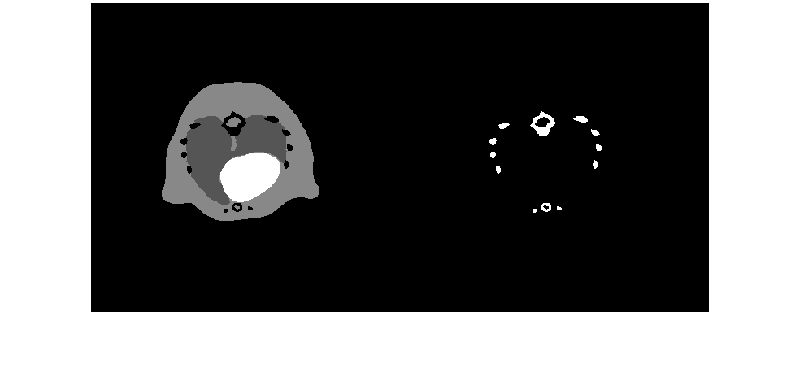

load("axial.mat");
imshowpair(axial(:,:,1),axial(:,:,2),'montage')
title('Density:water of soft tissue, bone');


tissue = axial(:,:,1);
tissue = padarray(tissue, [10, 10]);

% imshow(tissue, []); 
% title('tissue') 
% colorbar

Research for the reconstruction of 360/n detectors, which means one detector is responsible for the photon in n degrees. In my code, n corresponde to batch_detector

rng('default');
%For region ABO, the prob is 0.8 0.12 0.08
%Considering the different size of region.If we want to achieve the prob density is 0.8 0.12 0.08
%generated particles/area = density prob
%0.8 0.12 0.08=>1.6:0.12:0.32 =>0.8 0.06 0.14
area_series=randsrc(1,200,[2 1 3;0.8 0.06 0.14]);%Probability of organA is 80%

[x_organ1,y_organ1]=find(tissue==1.5);
[x_organ2,y_organ2]=find(tissue==0.5);
[x_organ3,y_organ3]=find(tissue<1.5&tissue>0.5);

attribute=zeros(length(area_series),4);

for i=1:length(area_series)
    if area_series(i)==1
        index1=randi(3301);
        locx=x_organ1(index1);%locx is the index of row, which represent y-axis location
        locy=y_organ1(index1);
    elseif area_series(i)==2
        index2=randi(6770);
        locx=x_organ2(index2);
        locy=y_organ2(index2);
    elseif area_series(i)==3
        index3=randi(13638);
        locx=x_organ3(index3);
        locy=y_organ3(index3);
    end
    degree=randi(360);
    attribute(i,:)=[area_series(i),locy,locx,degree];
end

Lines=zeros(size(attribute,1),3);
Lines_origin=zeros(size(attribute,1),3);
for i=1:size(attribute,1)
    %xsin-ycos-asin+bcos
    Lines(i,:)=[sin(deg2rad(attribute(i,4))),-cos(deg2rad(attribute(i,4))),-sin(deg2rad(attribute(i,4)))*attribute(i,2)+cos(deg2rad(attribute(i,4)))*attribute(i,3)];
    Lines_origin(i,:)=[sin(deg2rad(attribute(i,4))),-cos(deg2rad(attribute(i,4))),-sin(deg2rad(attribute(i,4)))*(attribute(i,2)-200)+cos(deg2rad(attribute(i,4)))*(attribute(i,3)-200)];
end

%Compute the intersection points of the lines and the image border.
points = lineToBorderPoints(Lines,[400,400]);

x_circle = [];
y_circle = [];
r_circle = 150;
batch_detector=1;%the number of degrees for 1 detector

for i=1:batch_detector:360
    x_circle((i-1)/batch_detector+1) = r_circle * cos(i*2*pi/360)+200;
    y_circle((i-1)/batch_detector+1) = r_circle * sin(i*2*pi/360)+200;
end

%struct_detector=struct('degree',keys,'position_x',x_circle-200,'position_y',y_circle-200);
detector_loc=[x_circle;y_circle]';
detector_series=1:batch_detector:360;
projection_loc=zeros(length(area_series),3);%nearest one detector on this direction
projection_loc2=zeros(length(area_series),4);%nearest two detectors on this direction

for i=1:size(attribute,1)
    syms x real
    syms y real
    %assumeAlso(in(x,'integer'));
    %s=solve(x+y+1==0,x^2+y^2==200^2,x,y)
    s=solve(Lines_origin(i,1)*x+Lines_origin(i,2)*y+Lines_origin(i,3)==0,x^2+y^2==150^2,x,y);
    sol_x=double(round(s.x));
    sol_y=double(round(s.y));

    %find nearest detector in one direction
    if  sol_x
        dist1=norm(attribute(i,2:3)-[200 200]-[sol_x(1) sol_y(1)]);
        dist2=norm(attribute(i,2:3)-[200 200]-[sol_x(2) sol_y(2)]);
        if dist1>dist2
            Intersection_loc_near=[sol_x(2)+200 sol_y(2)+200];
            Intersection_loc_far=[sol_x(1)+200 sol_y(1)+200];
        else
            Intersection_loc_near=[sol_x(1)+200 sol_y(1)+200];
            Intersection_loc_far=[sol_x(2)+200 sol_y(2)+200];
        end

        Euc_distances=sqrt(sum(bsxfun(@minus, detector_loc, Intersection_loc_near).^2,2));%compute Euclidean distances
        closest_point_index = find(Euc_distances==min(Euc_distances));
        closest_point_index=closest_point_index(1);
        projection_loc(i,:)=[closest_point_index,detector_loc(closest_point_index,1),detector_loc(closest_point_index,2)];
    
        Euc_distances2=sqrt(sum(bsxfun(@minus, detector_loc, Intersection_loc_far).^2,2));%compute Euclidean distances
        closest_point_index2 = find(Euc_distances2==min(Euc_distances2));
        closest_point_index2=closest_point_index2(1);
        projection_loc2(i,:)=[detector_loc(closest_point_index,1),detector_loc(closest_point_index,2),detector_loc(closest_point_index2,1),detector_loc(closest_point_index2,2)];
    end   
end


First estimation is to draw a graph of densities of response(LOR), with the help of  bresenham line drawing algorithm.

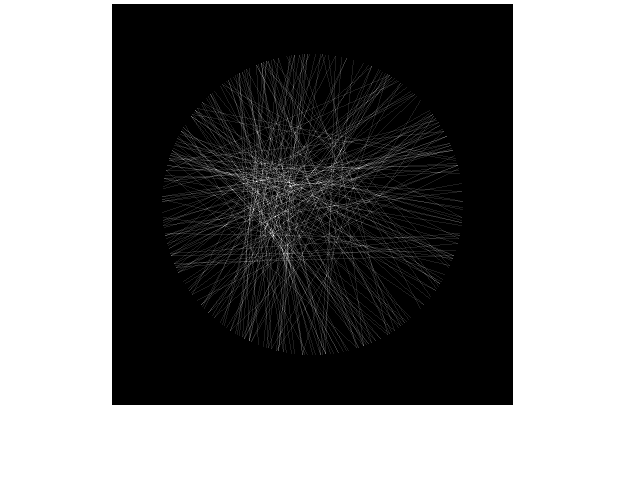

routes_x=[];
routes_y=[];
for i=1:size(points,1)
    %Bresenham line algorithm
    [x_list,y_list]= bresenham(projection_loc2(i,1),projection_loc2(i,2),projection_loc2(i,3),projection_loc2(i,4));
    routes_x=[routes_x;x_list];
    routes_y=[routes_y;y_list];
end


Recon=zeros(401,401);
for i=1:size(routes_x,1)
    Recon(routes_y(i)+1,routes_x(i)+1)=Recon(routes_y(i)+1,routes_x(i)+1)+1;
end

figure
fig_recon1=imshow(Recon,[]);

%saveas(fig_recon1,'Recon_360det_200itr.png');


Need to re-run this section to see the simulated animation of PET.

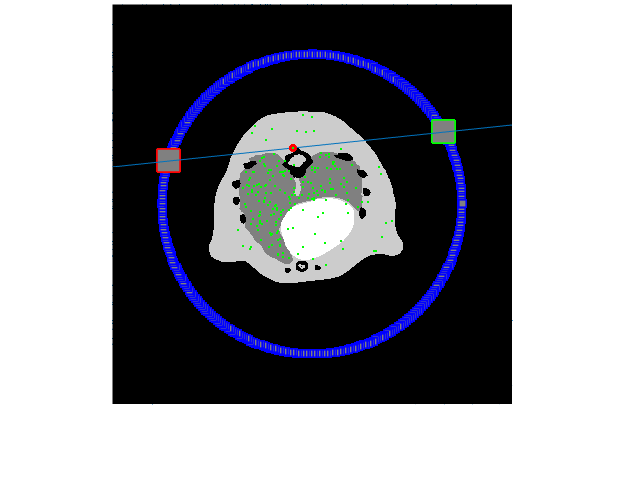

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.

Error in is2D>testOneAxes (line 34)
        camUp = get(ax,'CameraUpVector');

Error in is2D (line 23)
    retval = testOneAxes(ax);

Error in 

%----------------------------VISUALISATION of initial simulation-------------------------%
figure
for i=1:size(attribute,1)
    h2=plot(x_circle,y_circle,'--gs',...
    'LineWidth',1,...
    'MarkerSize',5,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5]);
    axis([0,400,0,400])
    axis square;
    hold on
    if ~projection_loc(i,1)==0
        plot(projection_loc(i,2),projection_loc(i,3),'--rs',...
            'LineWidth',1,...
            'MarkerSize',15,...
            'MarkerEdgeColor','r',...
            'MarkerFaceColor',[0.5,0.5,0.5]);
        hold on
        plot(projection_loc2(i,3),projection_loc2(i,4),'--gs',...
            'LineWidth',1,...
            'MarkerSize',15,...
            'MarkerEdgeColor','g',...
            'MarkerFaceColor',[0.5,0.5,0.5]);
        hold on
    end 

    line(points(i,[1,3])',points(i,[2,4])');
    hold on
    plot(attribute(i,2),attribute(i,3),'r.','MarkerSize',10)
    hold on
    plot(attribute(:,2),attribute(:,3),'g.','MarkerSize',1)
    hold on
    pause(0.05);

    h1=imshow(tissue);
    hold on
end

function [x y] = bresenham(x1,y1,x2,y2)
%Usage example:
%[x y]=bresenham(1,1,10,-5);
% plot(x,y,'or');
x1=round(x1); x2=round(x2);
y1=round(y1); y2=round(y2);
dx=abs(x2-x1);
dy=abs(y2-y1);
steep=abs(dy)>abs(dx);
if steep t=dx;dx=dy;dy=t; end

%The main algorithm goes here.
if dy==0 
    q=zeros(dx+1,1);
else
    q=[0;diff(mod([floor(dx/2):-dy:-dy*dx+floor(dx/2)]',dx))>=0];
end

%and ends here.

if steep
    if y1<=y2 y=[y1:y2]'; else y=[y1:-1:y2]'; end
    if x1<=x2 x=x1+cumsum(q);else x=x1-cumsum(q); end
else
    if x1<=x2 x=[x1:x2]'; else x=[x1:-1:x2]'; end
    if y1<=y2 y=y1+cumsum(q);else y=y1-cumsum(q); end
end

end
